# Week 1: Intro to Matlab and Simulink

#### Author: Keith Chester

#### E-mail: kchester@wpi.edu

## Introduction

For the first week of the course *RBE 500 - Foundations of Robotics* - we were tasked with an assignment to demonstrate proficiency in MATLAB by completing the following tasks:

- *Write down the function g(t) that has the shape of a sine wave that  increases linearly in frequency from 0Hz at t = 0s to 5Hz at t = 10s.*

- *Plot the graph of this function using MATLAB's plot command.*

- *Add to the same figure in a different color a graph of the same function sampled continuously at 5Hz.*

## Methods

There are two stages to this problem. The first is to break down the problem mathematically so that we can model what we wish to accomplish. The second is to create a program that will execute our derived model and perfom plotting.

In order to derive our model, we will be first calculating the frequency based on conditions provided. As described, the instantaneous frequency acts as a linear function of time, meaning we can solve a resulting slope and bias to solve for its equation.

Once we have the instantaneous frequency, we can calculate the phase at a time *t* for the *g(t)* by integrating the instantaneous frequency function and multiplying it by *2*pi*. **[1]**

Once we have the equations, we can plot it using the **plot** function. We'll make use of a time range with more steps to plot a smooth function, and then create a second time range with the requested 5 Hz sampling rate to plot the second line.

### Modeling the Problem

We need to figure out the frequency of the function *g(t) *as a function of *t*. The question specifies that the frequency is changing linearly, thus implying a linear function to represent the function at a given time *t*. The question goes on to provide significant information for this - the initial and final frequencies at specified times.

We can solve for a simple linear function using the math below. Given that ***y=mx + b***, we solve for our slope *m*:

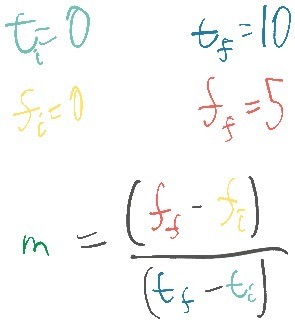

**m** is thus equivalent to the change in frequency over the change in time. From here, we need to calculate our bias, **b**:

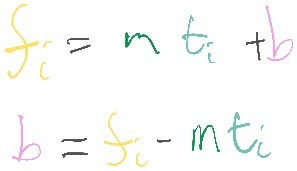

...which, given our initial conditions, is simply 0. Still, if we wish to make this functionality modular and to support other specified conditions, we should make note of the bias.

Once we have the frequency, we need to find the phase of the sinusoidal wave at a given *t*. To do so, we must realize that

- The frequency we calculate at any given time is the instananeous frequency, meaning that

- ...to find the given phase at a time *t* for the wave, we need to take the definite integral from time *0* to *t *and multiply it by 2*pi. 

The integral of our linear function is simply:

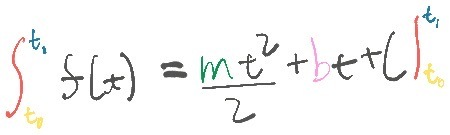

...with the constant factor C factoring out as it is a definite integral. *t_0* will be 0, resulting in just the value of *m/2*t^2 + b*t*.

Filling in with our initial values, we get that the resulting instantaneous frequency is *f(t)=t/2*.

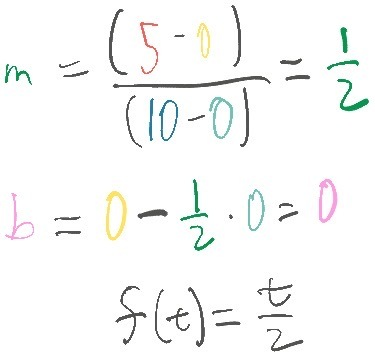

The resulting phase of our wave at time *t* is thus the integral of *t/2* * 2*pi:

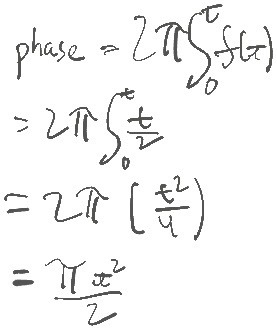

...but our code will be more generic, to support other possible initial conditions.

## Results

Below you can configure the initial settings and see its effect on the result. For the first settings, the initial and final time, please select a value between 0 and 60 seconds. Please note that the *initial_time* must be set prior to the *final_time*, as time travel is frowned upon (real sinusoidal waves can only have positive frequencies, and we are not dealing with complex values here).

initial_time =0;
final_time = 10;

The next initial settings are the frequencies in Hertz:

initial_frequency = 0;
final_frequency = 5;

From here, we can build our plots. We utilize two time scales between our initial and final times - the first is fine with many discrete steps, and the second is specified by our problem - 5Hz sampling rate. The fine time scale is to properly graph our wave without choppiness, whereas the second is simply following instructions. The red plot is the fine time range and the green plot is the 5Hz sample rated time range.

Note that the calculations are being performed in a function *g_t*, which is placed at the end of the **Results** section.

% Create a range of time to plot against. We specifically use small time
% steps to allow smoother plotting for this range.
t = initial_time:0.001:final_time;
% Please look at the included g_t.m in order to see the code for the
% calculations.
y = g_t(t, initial_time, initial_frequency, final_time, final_frequency);

plot(t, y, 'red')

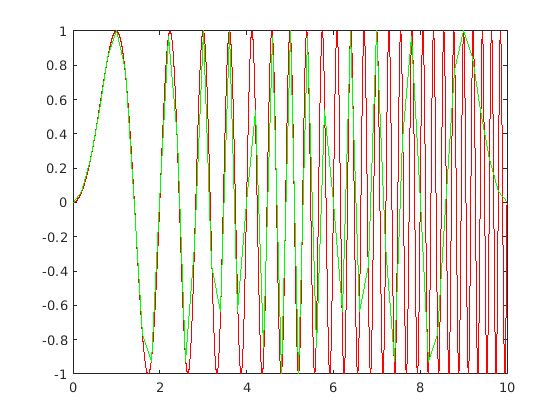

% The instructions also ask for a 5hz sample rate, or a sampling once every
% 0.2 seconds. This results in a "choppier" wave and is drawn below:
hold on
t2 = 0:0.2:10;
y2 = g_t(t2, initial_time, initial_frequency, final_time, final_frequency);
plot(t2, y2, 'green')
hold off

The below figure demonstrates the expected output for the original initial conditions:

### Functions

Unfortunately, MATLAB has a requirement to put functions towards the end of the script. Per request to place all code in this livescript file, that means we need to place all of our functions towards the end of the results.

For this assignment, we only defined one function, contained below. The math behind the function is discussed above.

function y = g_t(t,initial_time, initial_frequency, final_time, final_frequency)
%g_t ( g(t) ) calculates the resulting function from the desired intiail
%conditions specified for the linearly changing frequency. The mathematics
%used to derive the result below is explained in the livescript.

% Solve for the linear equation first. First, our slope
m = (final_frequency - initial_frequency) / (final_time-initial_time);
% Then solve for our b
b = initial_frequency - (m*initial_time);

% Now that we have m and b, we have y=mx+b. Now we need to solve for the
% integral of this:
integrated_frequency = (m * t.^2 * 1/2) + (b * t);

% Finally, the resulting phase of a given sinusoidal wave is 2*pi 
y = sin(2*pi*integrated_frequency);

end

## Discussion

The plotted graph demonstrates the requested function *g(t)* as prescribed by the assigned problem. The ultimate goal of the assignment was to act as an introduction to MATLAB and its tools, as well as to adopt working in the requested format of the course. This format, however, is difficult to follow given the limited socpe of the assignment. This author willingly admits this could be frustration garnered from a lack of experience, however.

The most notable problem for clear, concise explanation and walk through of code within MATLAB's LiveScript is the requirement to put functions either in a separate file or at the end of the file itself.

I created an animated plot for the above graphs, but found the speed of the animation far too slow and abandoned the feature.

## Citations

**[1]** *Instantaneous phase and frequency - Wikipedia Febuary 6, 2021 https://en.wikipedia.org/wiki/Instantaneous_phase_and_frequency#Instantaneous_frequency*